# MATLAB & Mobile Phone Sensors

Using "MATLAB Mobile" to access organic cell phone sensors and to export data file to "MATLAB Drive." 

Experiment A: Turn on the acceleration sensor. Place the cell phone flat on the table. Collect data for 1-2 minutes. Download the data file from MATLAB Drive.

Load acceleration data file to workspace

load("C:\Users\m260477\Desktop\EW202\ICE\ICE2\Z_Acceleration.mat")

Plot vertical acceleration data (Z axis data when the cell phone is placed face-up on table)

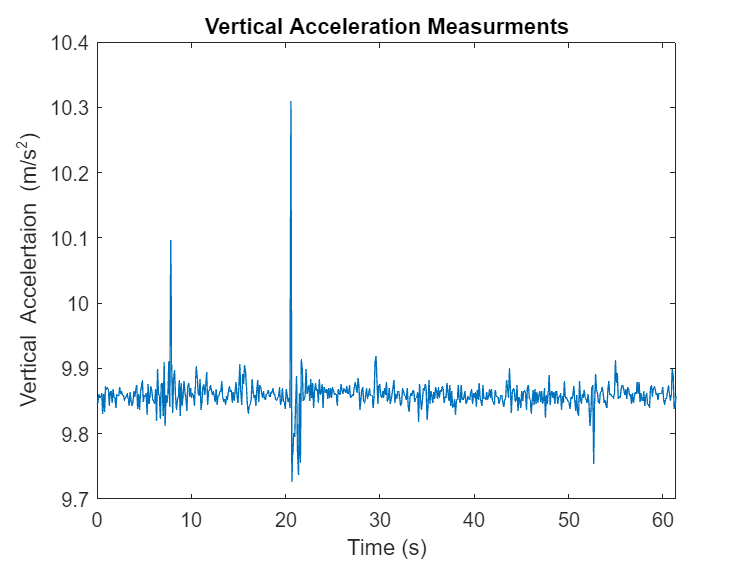

time = Acceleration.Timestamp; % grab timestamps
x = seconds(cumsum(diff(time))); % calculate the difference between timestamps and cumulative sum them 
x = [0; x]; % time starts at 0 seconds
z = Acceleration.Z; % grab z-axis acceleration
plot(x,z) % plot acceleration vs. time 
title("Vertical Acceleration Measurments")
xlabel("Time (s)")
ylabel("Vertical Accelertaion (m/s^2)")
xlim("tight")

Find the latest value of the vertical acceleration

z(end)

ans = 9.8582

Is this value a good estimate of the steady state?

Not really... Its just the last value. Doesn't represent the whole sample data collected.

Find a better estimate of the steady-state value

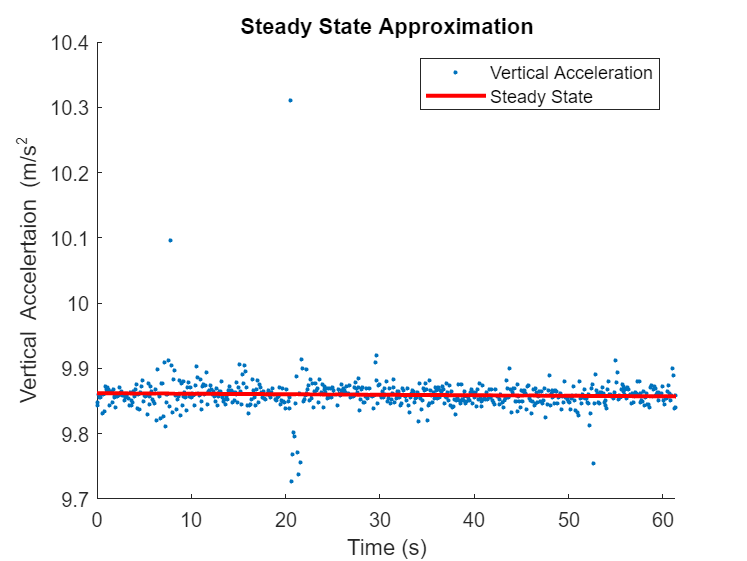

scatter(x,z,".") % scatter plot acceleration vs. time 
pfit = polyfit(x,z,1); % fit line to data 
pval = polyval(pfit,x); % evaulate fitted line
hold on
plot(x,pval,"r","LineWidth",2) % plot fitted line
title("Steady State Approximation")
legend(["Vertical Acceleration" "Steady State"])
xlabel("Time (s)")
ylabel("Vertical Accelertaion (m/s^2")
xlim("tight"),
hold off

trimmed_mean_estimate = trimmean(z,10) % grab 10% trimmed mean

trimmed_mean_estimate = 9.8591

What is the value of the acceleration of gravity?

9.81

Write a logical IF statement to declare (or not) error in the measurement of g=9.81 m/s^2:

if trimmed_mean_estimate ~= 9.81 % check if estimate is equal to 9.81
    disp('There is measurement error')
else
    disp('There is no measurement error')
end

There is measurement error


How is acceleration measured in general? What type of accelerometer is inside the cell phone?

Accleration is the change in velocity with resepect to time. 

MEMS-based accelerometer.

[STRETCH] Experiment B: Generate orientation data (e.g., change the pitch anlge, that is, the angle from the table to the plane of the phone). Load orientation data file to workspace

load("C:\Users\m260477\Desktop\EW202\ICE\ICE2\Y_Acceleration.mat")

Plot orientation data

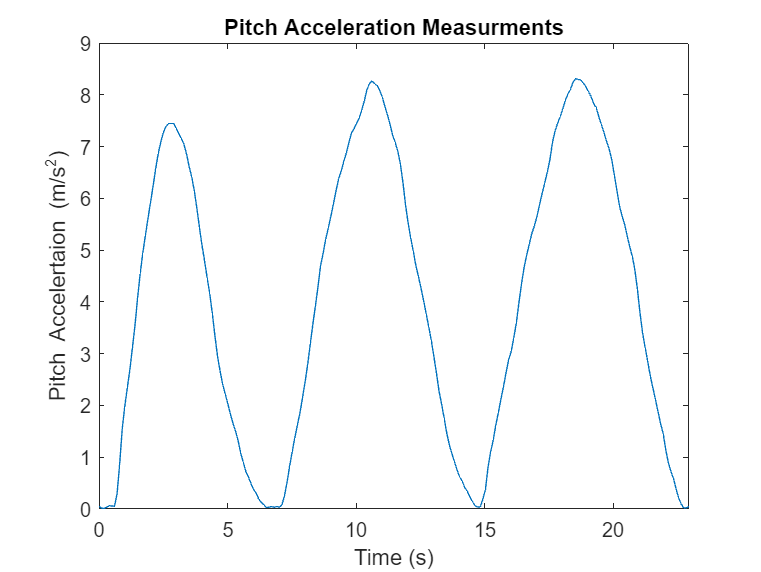

time = Acceleration.Timestamp; % grab timestamps
x = seconds(cumsum(diff(time))); % calculate the difference between timestamps and cumulative sum them 
x = [0; x]; % time starts at 0 seconds
y = Acceleration.Y; % grab z-axis acceleration
plot(x,y) % plot acceleration vs. time 
title("Pitch Acceleration Measurments")
xlabel("Time (s)")
ylabel("Pitch Accelertaion (m/s^2)")
xlim("tight")

Does the graph capture the pitch angle correctly?

Yes!

*Prof Kiriakos Kiriakidis (Jan 18, 2024).*